# **Linear and Extended Kalman Filter Design for a Pendulum System**

**Clear all, add path, open Simulink model**

clear;
clf;
clc;
addpath("helperFunctions");
open_system("models/virtualPendulumModel");

## Kalman Filter to estimate the angular position of the linearized pendulum system

model.ts = 0.001; % Sampling time [s]
model.m = 1; % Pendulum mass [kg]
model.L = 1; % Pendulum length [m]
model.g = 9.81; % Gravity [m/s^2]

% Pendulum IC
model.theta0 = pi/18; 
model.theta_dot0 = 0;

The **continuous-time** pendulum system model is:


$$\dot{\theta} = \dot{\theta} \\
\ddot{\theta} = -\frac{g}{L}sin(\theta) + \frac{1}{mL^2}\tau$$


The **linearized continuous-time** model is:


$$A_c = \pmatrix{0 & 1 \cr -\frac{g}{L} & 0} ,\quad B_c = \pmatrix{0 \cr \frac{1}{mL^2}}, \quad C_c = \pmatrix{1 & 0 }, \quad D_c = 0$$


% Linearized continuos-time SS model
model.con_lin.A = [0 1;
     -model.g/model.L 0];
model.con_lin.B = [0;
     1];
model.con_lin.C = [1 0];
model.con_lin.D = 0;

By applying forward euler transformation,


$$\dot{\theta} \approx \frac{\theta_{k+1} - \theta_k}{T_s}$$


the corresponding **discrete-time** pendulum system model can be found:


$$\theta_{k+1} = \theta_k + T_s \omega_k \\
\omega_{k+1} = \omega_k -T_s\frac{g}{L}sin(\theta_k) + \frac{T_s}{mL^2}\tau_k$$


The **linearized discrete-time** model is:


$$A_d = \pmatrix{1 & T_s \cr -T_s\frac{g}{L} & 1} ,\quad B_d = \pmatrix{0 \cr \frac{T_s}{mL^2}}, \quad C_d = \pmatrix{1 & 0 }, \quad D_d = 0$$


% Linearized discrete-time SS model
model.dis_lin.A = [1 model.ts;
     -model.ts*model.g/model.L 1];
model.dis_lin.B = [0;
     model.ts];
model.dis_lin.C = [1 0];
model.dis_lin.D = 0;

% Process noise
model.Q = diag([0 1e-3]);
model.R = 1e-4;

% Initial state and covariance estimates
model.dis_lin.x0est = [model.theta0; model.theta_dot0];
model.dis_lin.P0 = diag([1 1]);

### **Visualize the motion of the pendulum (No process noise)**

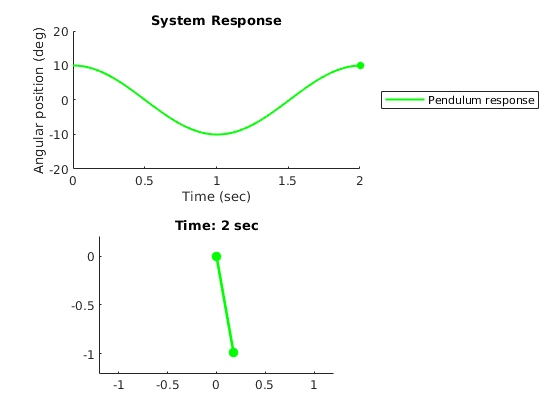

% Set parameters
model.simTime = 2;
set_param("virtualPendulumModel/Process noise", "Cov", "0");

% Simulates the pendulum model
simOut = sim("models/virtualPendulumModel", model.simTime);

% Plot system response
figure(1);
animatePendulum(simOut.tout, simOut.theta.signals(1).values, [], [], rad2deg(model.theta0));

### Compare measured to actual pendulum response (No process noise)

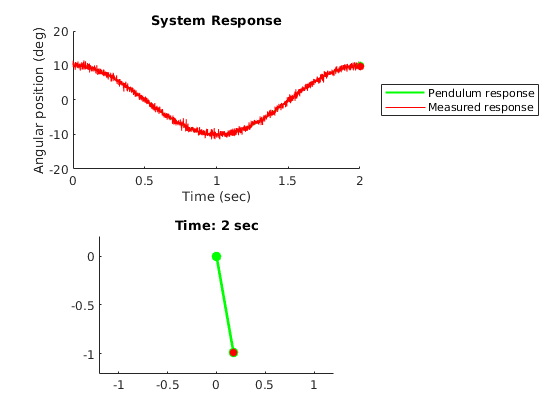

% Set parameters
model.simTime = 2;
set_param("virtualPendulumModel/Process noise", "Cov", "0");

% Simulates the pendulum model
simOut = sim("models/virtualPendulumModel", model.simTime);

% Plot system response
figure(2);
animatePendulum(simOut.tout, simOut.theta.signals(1).values, simOut.theta.signals(2).values, [], rad2deg(model.theta0));

### Compare measured, actual and estimated pendulum response 

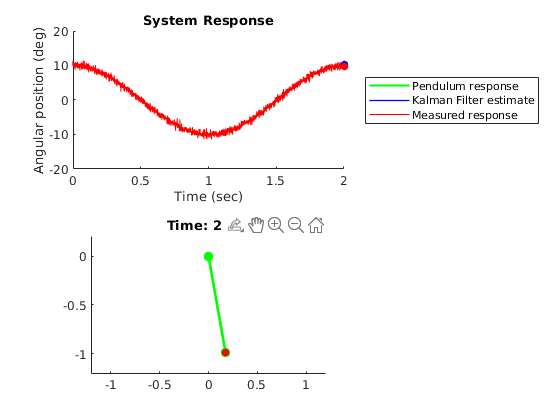

% Set parameters
model.simTime = 2;
set_param("virtualPendulumModel/Process noise", "Cov", "model.Q(2,2)*model.ts");

% Simulates the pendulum model
simOut = sim("models/virtualPendulumModel", model.simTime);

% Plot system response
figure(3);
animatePendulum(simOut.tout, simOut.theta.signals(1).values, simOut.theta.signals(2).values, simOut.theta.signals(3).values, rad2deg(model.theta0));

### Angular IC: pi/16, pi/14

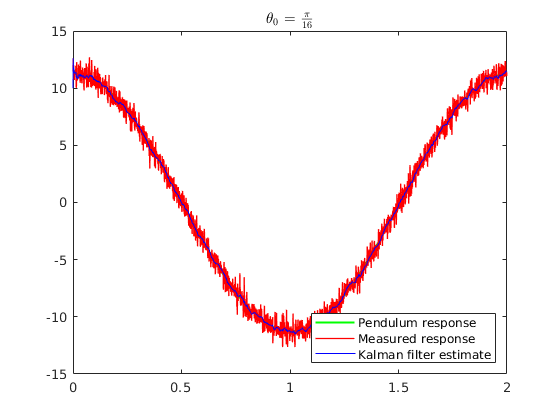

% Initial true state, state and covariance estimates
model.simTime = 2;
model.theta0 = pi/16;
model.lin.x0est = [pi/18; model.theta_dot0];
model.lin.P0 = diag([1 1]);

% Simulates the pendulum model
simOut = sim("models/virtualPendulumModel", model.simTime);

% Plot system response
figure(4);
plot(simOut.tout, simOut.theta.signals(1).values, 'g', LineWidth = 1.5);
hold on;
plot(simOut.tout, simOut.theta.signals(2).values, 'r', LineWidth = 1);
hold on;
plot(simOut.tout, simOut.theta.signals(3).values, 'b', LineWidth = 0.5);
title('$\theta_0$ = $\frac{\pi}{16}$', 'interpreter','latex');
legend('Pendulum response', 'Measured response', 'Kalman filter estimate', 'Location','southeast');
hold off;

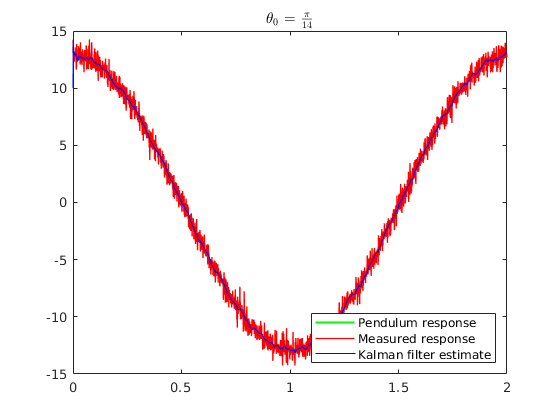

% Initial true state, state and covariance estimates
model.theta0 = pi/14;
model.lin.x0est = [pi/18; model.theta_dot0];
model.lin.P0 = diag([1 1]);

% Simulates the pendulum model
simOut = sim("models/virtualPendulumModel", model.simTime);

% Plot system response
figure(5);
plot(simOut.tout, simOut.theta.signals(1).values, 'g', LineWidth = 1.5);
hold on;
plot(simOut.tout, simOut.theta.signals(2).values, 'r', LineWidth = 1);
hold on;
plot(simOut.tout, simOut.theta.signals(3).values, 'b', LineWidth = 0.5);
title('$\theta_0$ = $\frac{\pi}{14}$', 'interpreter','latex');
legend('Pendulum response', 'Measured response', 'Kalman filter estimate', 'Location','southeast');
hold off;

### R estimation

% Pendulum rest position: theta0 = 0, theta_dot0 = 0
% Set parameters
model.simTime = 5;
set_param("virtualPendulumModel/Process noise", "Cov", "0");
set_param("virtualPendulumModel/rad2deg", "Gain", "1");
model.theta0 = 0;
model.theta_dot0 = 0;

% Simulates the pendulum model
simOut = sim("models/virtualPendulumModel", model.simTime);

% Compute sample mean
model.R_est.sample_mean = 0;
for i = 1:length(simOut.theta.signals(2).values)

    model.R_est.sample_mean = model.R_est.sample_mean + simOut.theta.signals(2).values(i);
end
model.R_est.sample_mean = model.R_est.sample_mean / length(simOut.theta.signals(2).values);

% Compute sample variance
model.R_est.sample_variance = 0;
for i = 1:length(simOut.theta.signals(2).values)

    model.R_est.sample_variance = model.R_est.sample_variance + (simOut.theta.signals(2).values(i) - model.R_est.sample_mean)^2;
end
model.R_est.sample_variance = model.R_est.sample_variance / length(simOut.theta.signals(2).values);

### Effect of R on KF output

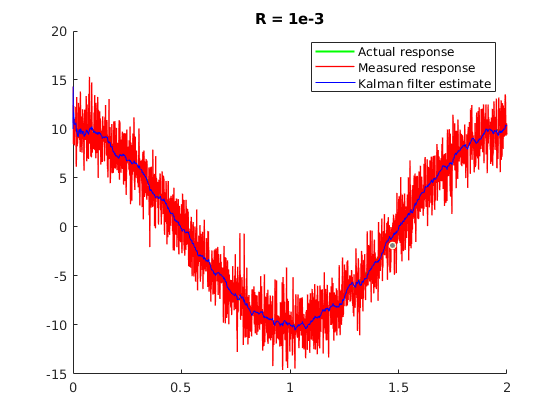

% R = 1e-3
% Set parameters
model.R = 1e-3;
model.simTime = 2;
set_param("virtualPendulumModel/Process noise", "Cov", "model.Q(2,2)*model.ts");
set_param("virtualPendulumModel/Measurement noise", "Cov", "model.R*model.ts");
set_param("virtualPendulumModel/rad2deg", "Gain", "180/pi");
model.theta0 = pi/18;

% Simulates the pendulum model
simOut = sim("models/virtualPendulumModel", model.simTime);
figure(7);
hold on;
plot(simOut.tout,simOut.theta.signals(1).values,'g', LineWidth = 1.5);
plot(simOut.tout,simOut.theta.signals(2).values,'r', LineWidth = 1);
plot(simOut.tout,simOut.theta.signals(3).values,'b', LineWidth = 0.5);
title('R = 1e-3');
legend("Actual response","Measured response","Kalman filter estimate");

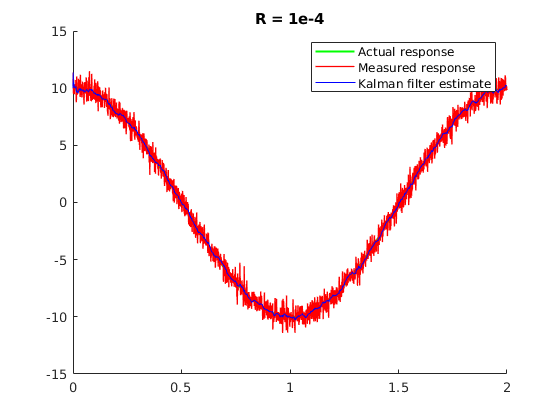

% R = 1e-4
% Set parameters
model.R = 1e-4;
set_param("virtualPendulumModel/Measurement noise", "Cov", "model.R*model.ts");

% Simulates the pendulum model
simOut = sim("models/virtualPendulumModel", model.simTime);
figure(6);
hold on;
plot(simOut.tout,simOut.theta.signals(1).values,'g', LineWidth = 1.5);
plot(simOut.tout,simOut.theta.signals(2).values,'r', LineWidth = 1);
plot(simOut.tout,simOut.theta.signals(3).values,'b', LineWidth = 0.5);
title('R = 1e-4');
legend("Actual response","Measured response","Kalman filter estimate");

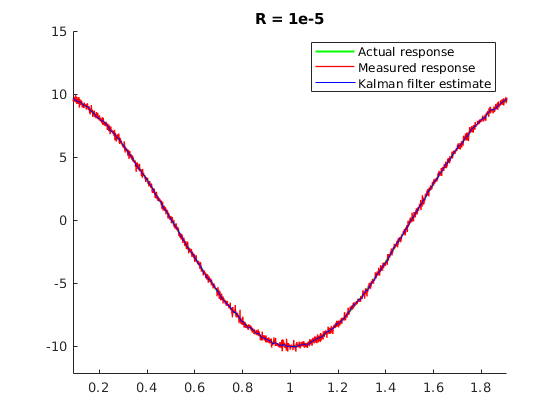

% R = 1e-5
% Set parameters
model.R = 1e-5;
set_param("virtualPendulumModel/Measurement noise", "Cov", "model.R*model.ts");

% Simulates the pendulum model
simOut = sim("models/virtualPendulumModel", model.simTime);
figure(8);
hold on;
plot(simOut.tout,simOut.theta.signals(1).values,'g', LineWidth = 1.5);
plot(simOut.tout,simOut.theta.signals(2).values,'r', LineWidth = 1);
plot(simOut.tout,simOut.theta.signals(3).values,'b', LineWidth = 0.5);
title('R = 1e-5');
legend("Actual response","Measured response","Kalman filter estimate");

### Effect of Q on KF output

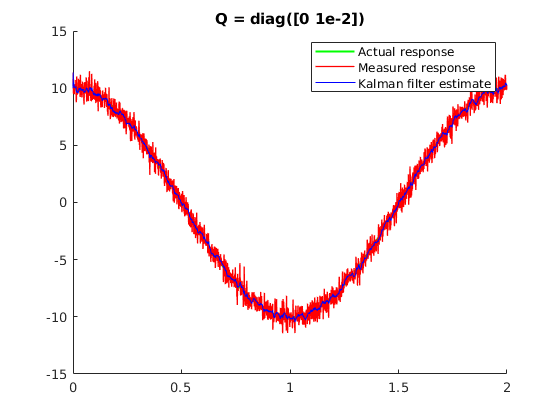

% Q = diag([0 1e-2]);
% Set parameters
model.R = 1e-4;
model.Q = diag([0 1e-2]);
set_param("virtualPendulumModel/Process noise", "Cov", "model.Q(2,2)*model.ts");

% Simulates the pendulum model
simOut = sim("models/virtualPendulumModel", model.simTime);
figure(10);
hold on;
plot(simOut.tout,simOut.theta.signals(1).values,'g', LineWidth = 1.5);
plot(simOut.tout,simOut.theta.signals(2).values,'r', LineWidth = 1);
plot(simOut.tout,simOut.theta.signals(3).values,'b', LineWidth = 0.5);
title('Q = diag([0 1e-2])');
legend("Actual response","Measured response","Kalman filter estimate");

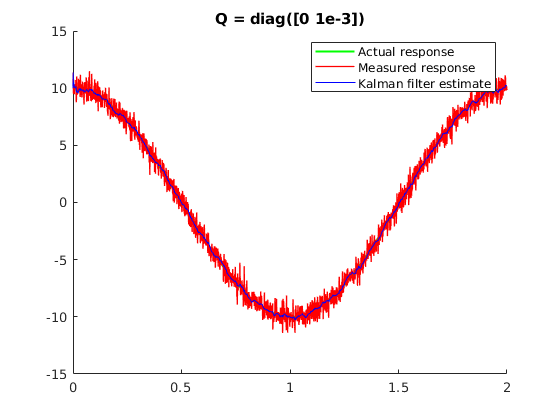

% Q = diag([0 1e-3]);
% Set parameters
model.Q = diag([0 1e-3]);
set_param("virtualPendulumModel/Process noise", "Cov", "model.Q(2,2)*model.ts");
set_param("virtualPendulumModel/Measurement noise", "Cov", "model.R*model.ts");

% Simulates the pendulum model
simOut = sim("models/virtualPendulumModel", model.simTime);
figure(9);
hold on;
plot(simOut.tout,simOut.theta.signals(1).values,'g', LineWidth = 1.5);
plot(simOut.tout,simOut.theta.signals(2).values,'r', LineWidth = 1);
plot(simOut.tout,simOut.theta.signals(3).values,'b', LineWidth = 0.5);
title('Q = diag([0 1e-3])');
legend("Actual response","Measured response","Kalman filter estimate");

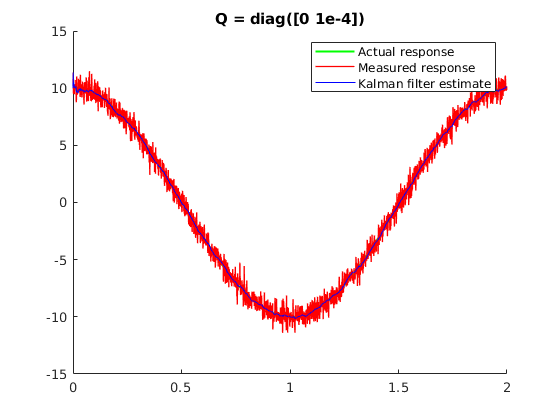

% Q = diag([0 1e-4]);
% Set parameters
model.Q = diag([0 1e-4]);
set_param("virtualPendulumModel/Process noise", "Cov", "model.Q(2,2)*model.ts");

% Simulates the pendulum model
simOut = sim("models/virtualPendulumModel", model.simTime);
figure(11);
hold on;
plot(simOut.tout,simOut.theta.signals(1).values,'g', LineWidth = 1.5);
plot(simOut.tout,simOut.theta.signals(2).values,'r', LineWidth = 1);
plot(simOut.tout,simOut.theta.signals(3).values,'b', LineWidth = 0.5);
title('Q = diag([0 1e-4])');
legend("Actual response","Measured response","Kalman filter estimate");

### **Large initial angle : 40deg**

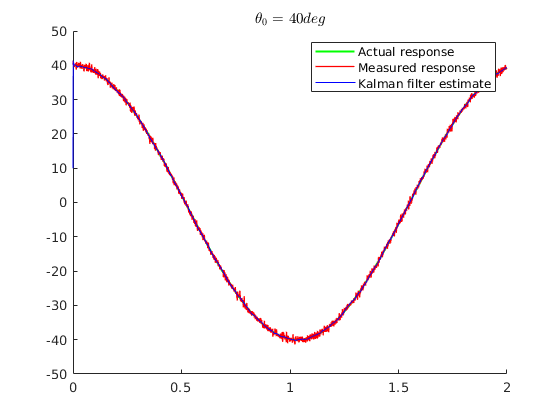

% Set parameters
model.simTime = 2;
model.theta0 = deg2rad(40);
model.Q = diag([0 1e-3]);
model.R = 1e-4;
set_param("virtualPendulumModel/Process noise", "Cov", "model.Q(2,2)*model.ts");
set_param("virtualPendulumModel/Measurement noise", "Cov", "model.R*model.ts");


% Simulates the pendulum model
simOut = sim("models/virtualPendulumModel", model.simTime);
figure(12);
hold on;
plot(simOut.tout,simOut.theta.signals(1).values,'g', LineWidth = 1.5);
plot(simOut.tout,simOut.theta.signals(2).values,'r', LineWidth = 1);
plot(simOut.tout,simOut.theta.signals(3).values,'b', LineWidth = 0.5);
title('$\theta_0$ = $40 deg$', 'interpreter','latex');
legend("Actual response","Measured response","Kalman filter estimate");

### Linear response vs NL response

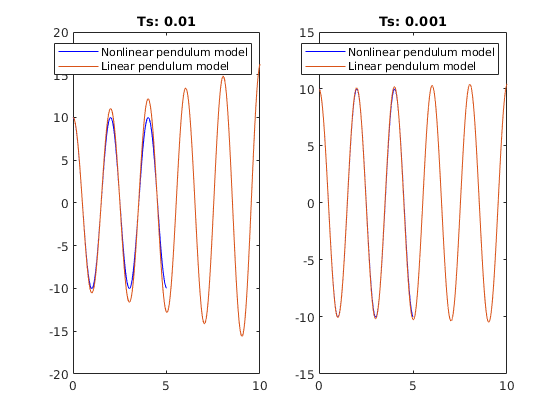

model.theta0 = deg2rad(10);
set_param('virtualPendulumModel/Process noise','Cov','0');

% Ts: 0.01
model.ts = 0.01;
model.dis_lin.A = [1 model.ts;
     -model.ts*model.g/model.L 1];
model.dis_lin.B = [0;
     model.ts];
model.dis_lin.C = [1 0];
model.dis_lin.D = 0;
sys1 = ss(model.dis_lin.A, model.dis_lin.B, model.dis_lin.C, model.dis_lin.D, model.ts);
[y1,t1] = initial(sys1,[model.theta0; 0], 0:model.ts:10);
simOut1 = sim("models/virtualPendulumModel", 5);

% Ts: 0.001
model.ts = 0.001;
model.dis_lin.A = [1 model.ts;
     -model.ts*model.g/model.L 1];
model.dis_lin.B = [0;
     model.ts];
sys2 = ss(model.dis_lin.A, model.dis_lin.B, model.dis_lin.C, model.dis_lin.D, model.ts);
[y2,t2] = initial(sys2,[model.theta0; 0], 0:model.ts:10);
simOut2 = sim("models/virtualPendulumModel", 5);

% Plot results
figure(13);
subplot(1,2,1);
plot(simOut1.tout,simOut1.theta.signals(1).values,'b');
hold on;
plot(t1,rad2deg(y1));
hold off;
title('Ts: 0.01');
legend('Nonlinear pendulum model','Linear pendulum model');

subplot(1,2,2);
plot(simOut2.tout,simOut2.theta.signals(1).values,'b');
hold on;
plot(t2,rad2deg(y2))
hold off;
title('Ts: 0.001');
legend('Nonlinear pendulum model','Linear pendulum model');

set_param('virtualPendulumModel/Process noise','Cov','model.Q(2,2)*model.ts');

## Extended Kalman Filter to estimate the angular position of the nonlinear pendulum system

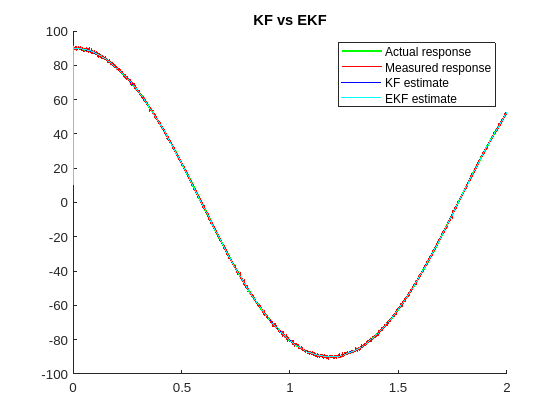

% Set parameters
model.simTime = 2;
model.theta0 = deg2rad(90);
model.Q = diag([0 1e-3]);
model.R = 1e-4;
set_param("virtualPendulumModel/Process noise", "Cov", "model.Q(2,2)*model.ts");
set_param("virtualPendulumModel/Measurement noise", "Cov", "model.R*model.ts");


% Simulates the pendulum model
simOut = sim("models/virtualPendulumModel", model.simTime);
figure(14);
hold on;
plot(simOut.tout,simOut.theta.signals(1).values,'g', LineWidth = 1.5);
plot(simOut.tout,simOut.theta.signals(2).values,'r', LineWidth = 1);
plot(simOut.tout,simOut.theta.signals(3).values,'b', LineWidth = 0.5);
plot(simOut.tout,simOut.theta.signals(5).values,'c', LineWidth = 0.5);
title('KF vs EKF');
legend("Actual response","Measured response","KF estimate", "EKF estimate");

model.theta0 = deg2rad(90);
model.ts = 0.001;
model.dis_lin.A = [1 model.ts;
     -model.ts*model.g/model.L 1];
model.dis_lin.B = [0;
     model.ts];